## Exam example 2022 EIT

## Antenna part:

Problem 9

You designed and measured a Patch antenna in the course which operated at 2,45 GHz in a 50 Ohm system. What should you do to tune your antenna if:

1.a (3%)        The operation frequency of your antenna is too high, say at 2,6 GHz?

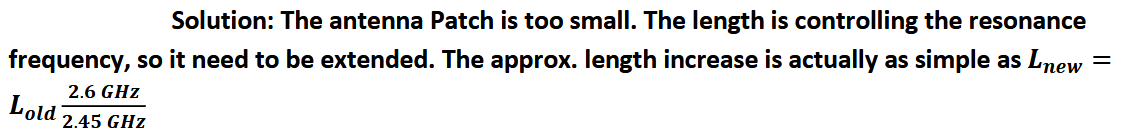

1.b (2%)        The impedance was too high, say 70 Ohm?

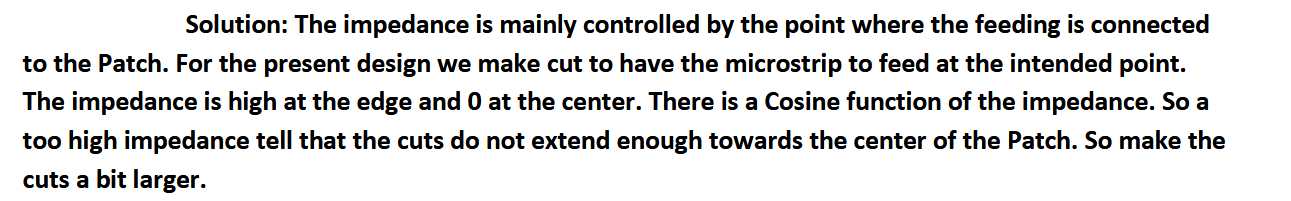

Problem 10

**Description**: Small satellites in an orbit close to the earth is under investigation for future 5G mobile systems as a new type of basestations. Which transmit power is required for such a system to work with similar phones as the ones we have today? 

The phone in present systems can receive correctly with a signal which is minimum -110 dBm on the input of its receiver. The phone antenna has a realized gain of some -10dBi due to losses in both the antenna itself and the user at the frequency of interest, 2.3 GHz. The distance from the earth to the satellite in so called Low Earth orbit is 500 KM.

2.a (5%)        If the area for the antenna on the satellite is 0,5 m2 how large a theoretical gain can be obtained at the frequency of 2,3 GHz?

**Solution**: $A=G\frac{\lambda^2 }{4\pi }$ hvor $\lambda =\frac{c}{f}$ Løs for G brormand!

syms x ptx
lambda = 3e8/2.3e9;
G = solve(0.5 == x*((lambda)^2)/(4*pi));
vpa(pow2db(G));

2.b (10%)      Find the minimum transmit power needed from the satellite if the gain of the antenna on the satellite is 20 dBi?

**Solution**: Brugt formel:$P_{\textrm{RX}} =P_{\textrm{TX}} {\left(\frac{\lambda }{4\pi R}\right)}^2 G_{\textrm{TX}} G_{\textrm{RX}}$ der antages at der er perfekt matching og polarizerings match for at denne formel kan benyttes! 

Gt = db2pow(20); % gain of satelite antenna
Gr = db2pow(-10); % gain of phone atenna;
Pr = 10^((-110-30)/10); %for at konvetere dbm brug dette erstat -110 med det skal være til den opgave. %Nødvendig power til tilfonen for at virke skal konverters til watt.
R = 500E3;
y = (lambda/(4*pi*R))^2;
Ptx = solve(Pr == ptx*y*Gt*Gr,ptx); % Solver for nødvendig power så telefonen kan modtage det.
vpa(Ptx); % Svar i watt

$$ans = 2.3204536569672312261995910843898$$

2.c (5%)    What more to consider when it is two way communication to a satellite instead of a ground base station? Hint; two way communication and polarization.

**Solution**:To have two link communication both links need to be fulfilled according to Friis equation. This is to say that link balance must be considred.

The gain of the antennas is the same for transmit as for receive if the same frequency is used.

The transmit powers might be different from a small battery powered phone and a satellite.

The receiver sensitivity might be better at the satellite as there is more space and power available than in a small phone.

Further the polarization must match. In communication with a satellite circular polarization is often used and if an antenna is receiving Left Hand Polarization if will transmit Right Hand Polarization – so must be considered

here

## Communication part:

Problem 1

Consider the network and edge-cost table in the figure below. Bellman-Ford algorithm is applied to find the shortest paths of the network 

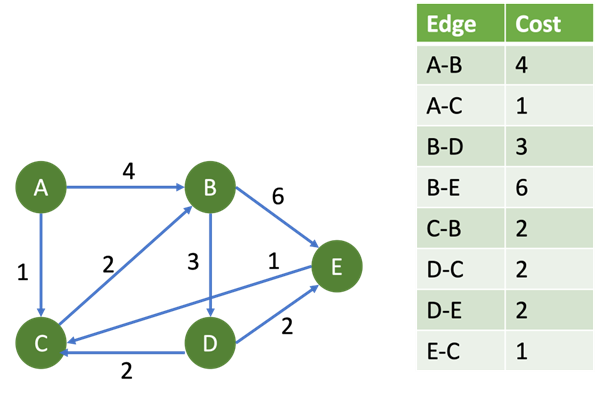

1. What is the maximum number of iterations required to complete the Bellman algorithm?

Med ingen cyckluser hvor vertices er cirklerne: $|V|-1$ edges hvilket giver: $5-1=4$

2. Construct the shortest path tree.

**Solution**: Iterate through total of 4 times and update for possible shortest route from A.

Problem 2

Assume that device A tries to send messages to device B. Propagation delay is assumed negligible between devices. The bandwidth of the line is 0,1 Mbit/s. Every frame is 200 bytes long and it is acknowledged with an ACK frame of 10 bytes. The timeout is 15ms (*timeout is the time device A waits for an ACK before retransmitting the frame*). Let us assume that the first frame is lost twice.

1. How long does it take until device A is notified about the successful reception of the first frame?

Pakken er tabt to gange ved første transmission hvilket giver: 15ms + 15ms = 30ms.

**Solution**: 

total_frame_time = (200*8)/0.1E6;
total_ack_time = (10*8)/0.1E6;
timeout = 15e-3+15e-3;
total_time = timeout+total_ack_time+total_frame_time;
num2sip(total_time);

2. How many times has A sent the first frame before receiving the ACK?

**Solution**: Transmission time for $T_{\textrm{tr}} =200\cdot 8/0\ldotp 1\textrm{E6}=16\textrm{ms}$hvilket betyder at før du har modtaget din første ACK så sender A en pakke mere hvilket giver 4 totalt.

3. How would you choose the timeout to make the procedure more efficient?

**Solution**:

eff = total_ack_time+total_frame_time;

Du vil have din timeout skal værre større 1.68 millisekunder!

Problem 3 

Consider a system is generating 20 bit frames connected through a shared 20 kbps channel using slotted ALOHA protocol.

1. Assume the load G is 0.2 packets per frame (G is the average number of packets per frame). Finding the actual throughput of the system. Hint: the efficiency in slotted ALOHA is $S={\textrm{Ge}}^{-G}$

Solution: Sæt ind i den givne formel og gang det derefter med 20 kbps for at finde din throughput din dejlige dreng :)

S = 0.2*exp(-0.2);
throughput = S*20E3;

2. What is the maximum possible throughput (in bits per second) of the system?

Solution:

maximum_throughput = 1*exp(-1)*20e3;

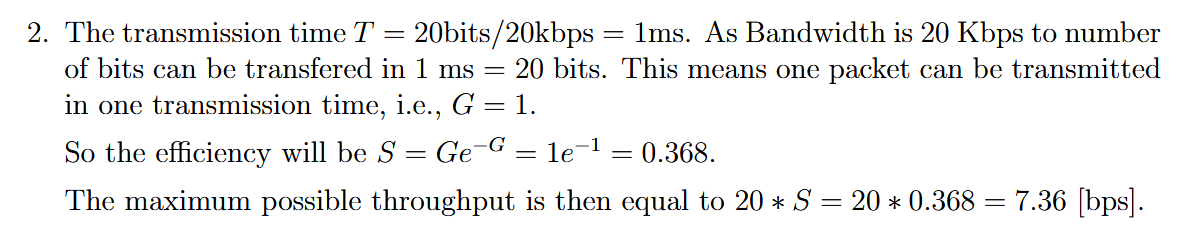

Problem 4

1. You have a receiver and transmitter with a link between them. The transmitter is sending 1 symbol every 1 microsecond, find the throughput of the system if:

a. 16 QAM modulation is used

Each symbol in 16-QAM carries **4 bits** (since $2^4 =16$).

Solution: T=10E6×4=4Mbps (Megabits per second). Ellers den her satan: $\frac{1\cdot 4}{1\cdot 1E-6}=4\mathrm{Mbps}$

b. QPSK modulation is used 

Solution: $\frac{1\cdot 2}{1\cdot 1E-6}=2\textrm{Mbps}$

2. Are the following questions false or true:

a. The number of points in the constellation of an 8-PSK is less than the number of points for an 8-QAM.

**Solution**: False cause they have the same number of points!

b. A modulation technique using 3 bits, there are 8 points in the constellation.

**Solution**: True but why?

c. OOK is a type of FSK.

Solution: False cause it is ASK(Ampltidue shift keying)

d. In QAM, the phase and amplitude of the carrier signal are varied based on the information in a digital signal.

**Solution** False QAM does not change the phase of I and Q but combined the two signales with different amplitudes they get a different phase.

Problem 6

1. If you are live-streaming a video (for example a Microsoft Teams meeting), which protocol is more suitable for real-time experience, TCP or UDP? Describe the advantage of the chosen protocol, and why you would pick it.

**Solution**: While both can be used for any kind of live-streaming, there is a significant difference in how they operate and for which type of application they individually are suitable. 

UDP is especially suitable for any kind traffic which does not require the entirety of the data to be received. Live streaming is one such traffic type, as the latency and real-time experience is more critical than receiving every video frame correctly as this may lead to stuttering and even more lag caused by the retransmission of single frames. Hence a deformed picture, or missing a video frame is not detrimental to the experience, whereas sudden lag spikes would be more apparent and frustrating.

2. Explain what the purpose of synchronicity is in a communication protocol, and if this is always relevant and required

**Solution**: 

Synchronicity is generally used to align the receiver and transmitter. From this we could think of synchronous and asynchronous communication. That could for the former be based on a slot-like structure of communication where at each discrete timestep you are in some state, known to the other parties. Hence it is possible to align the different parties with each other to make actions predictable. This could serve a purpose such as minimizing collisions, and is useful if multiple parties always, or often wish to transmit and have a guarantee on the expected availability, which requires scheduling in some form. Synchronicity is thus useful when you want a predictable outcome. For the latter, asynchronous protocols, these are useful when the actions of the parties are not deterministic and can change. For example parties are not always transmitting, but when they wish to transmit they would like to be fast and have the medium available. This type of communication is relevant and useful to ensure a system with many users that they do not take up resources not used, which ensures the users wishing to transmit and use the medium have resources available.

Both types of protocols are useful for different contexts and the relevance is system dependent.

Problem 7

1. Given a shared secret between Alice and Bob, how can data integrity be guaranteed to messages sent between Alice and Bob?

**Solution**: If a shared secret is given, hashing is a solution to ensure the integrity of messages sent between the 2.

By hashing the shared secret with the sent message, and appending the final hash the integrity of the message can be validated by the other party. 

If anyone were to make changes to the message without the proper “secret” the hash would simply be wrong, which can be evaluated by the receiver.

2. With public key cryptography how can you ensure authentication?

**Solution**: With public key cryptography the core feature is that the key used for decryption, only works with the key used for encryption (and vice versa as both can be used for

either.) 

Signatures is a way to ensure authentication by using the aforementioned feature. This would be done by signing a message using the private key when sending it. Upon reception the receiver can verify if the message was sent by the private key holder, by validating the signature using the public key for decryption.

This will ensure authentication as long as the private key is not leaked by storing it insecurely, and by ensuring that when receiving the public key that it truly it from who claims ownership. This is over the internet realized through certificate authorities., who certifies ownership of public keys. 

Naturally you can also “just” trust the ownership without other parties involvement.

3. Does the Diffie-Hellman algorithm provide a pair of symmetric or asymmetric keys?

**Solution**: A pair of asymmetric keys are provided by the algorithm. This is given from the fact diffie-hellman is used for public key cryptography, which relies on 2 different keys

(public and private).

4. What is the difference between the block and the stream cipher?

**Solution**: Block cipher processes the input one block of elements at a time, producing an output block for each input block.

Stream cipher processes the input elements continuously, producing output one element at a time, as it goes along.

Hence the differences lies in the block-based encryption of block ciphers where a certain size that must be encrypted at a time i.e. multiple bytes, and if the size is not met padding may be used to achieve the necessary block size.

Meanwhile the stream-cipher “streams” the encryption taking one element at a time (1 bit or 1 byte) in a continuous stream.

Problem 8:

In the lecture, we studied analog modulation schemes that turn feasible the transmission of analog sources of information. Answer the following.

1. Classify the analog modulation techniques that yield in the modulated signals depicted in the figure below by knowing that the carrier frequency is 10 Hz and the modulated signal is of the form m(t) = cos 2πt

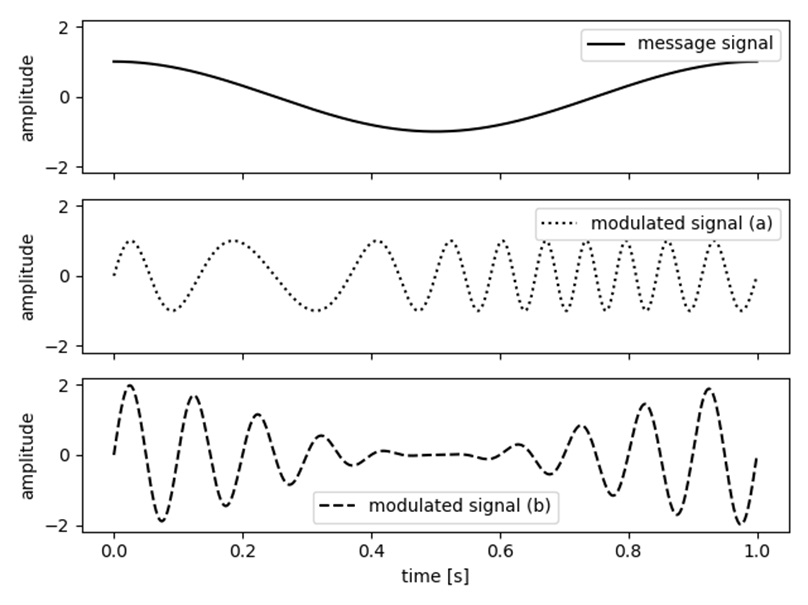

**Solution**: FM modulation og AM modulation i den rækkefølge for (a) og (b)

2. What are the main differences between these two analog modulation types? Compare them in terms of performance efficiency by giving pros and cons.

**Solution**: AM er trash brug FM :)). AM -> amplitude modulated, FM -> Frequency modulated. 

AM: PRO: Easy demodulation, CON: Quite susceptible for noise.

FM: PRO: More robust to noise and interference. CON: More complicated to demodulate.

3. Now, let us focus on the amplitude modulation. Recall the concept of a double-sideband suppressed-carrier transmission (DSB-SC) transmission, where the frequencies produced by AM are symmetrically spaced above and below the carrier frequency and the carrier level is reduced to the lowest practical level, ideally being completely suppressed. In a DSB system, the carrier is c(t) = A cos 2πfct, and the message signal is given by m(t) = sinc(t) + sinc2(t). Find the frequency domain representation and the bandwidth of the modulated signal.

**Solution**:

**Solution**: 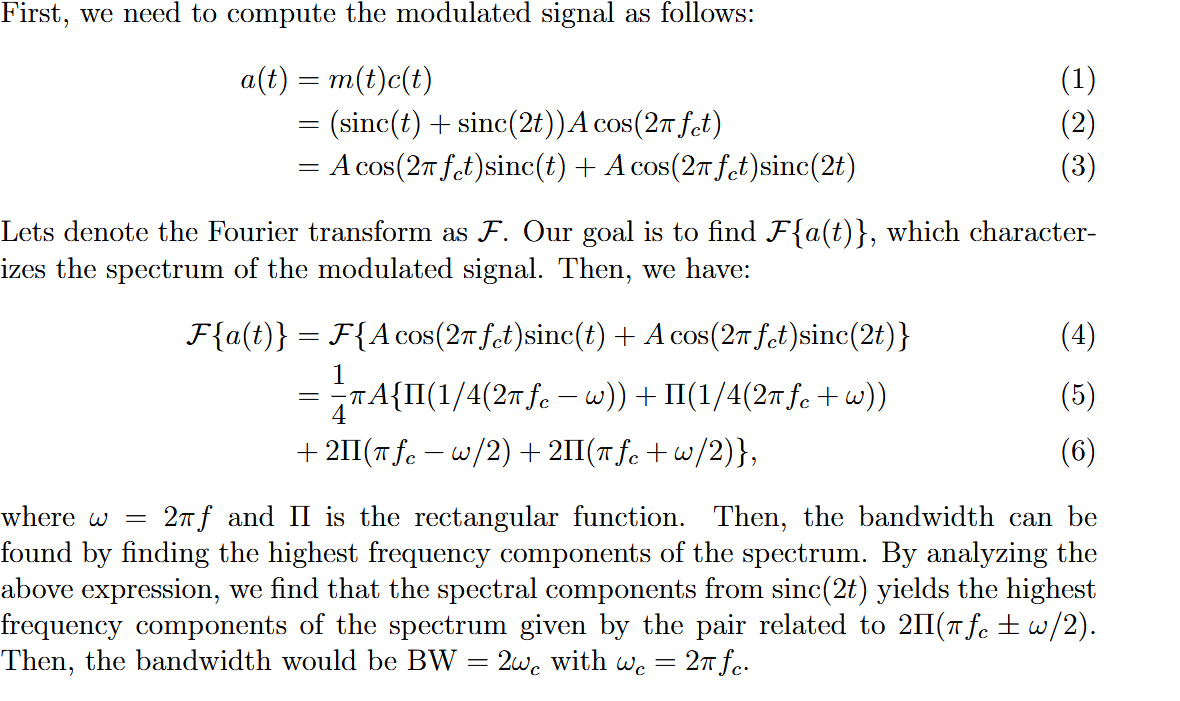

*Hint: Recall that the Fourier transform of a *sinc* function is a Boxcar or rectangular function up to a constant related to the normalization of the *sinc *function argument. (Thanks Petar you the 🐐🐐🐐)*